# Train Hardware Soft Robot

clear vars; close all; clc;
warning('off','all')

% Number of observables
numObs = 15;
load obsDecayDataC

## Visualize Training Data

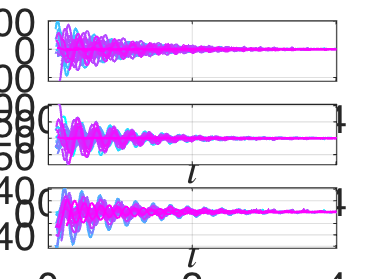

trajs = [13, 14, 15];
numCoord = length(trajs);
customFigure('subPlot',[numCoord 1]);
labels = ["$x_a$", "$y_a$", "$z_a$", ...
    "$x_b$", "$y_b$", "$z_b$", ...
    "$x_c$", "$y_c$", "$z_c$", ...
    "$x_d$", "$y_d$", "$z_d$", ...
    "$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:numCoord
    subplot(numCoord,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(trajs(iPlt)),'Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    for iObs = 1:numCoord
        subplot(numCoord,1,iObs);
        plot(oData{iTraj,1},oData{iTraj,2}(trajs(iObs),:),'Linewidth',1)
    end
end

## PCA

Just to check that from positions data we get 3 dominant modes as we expect

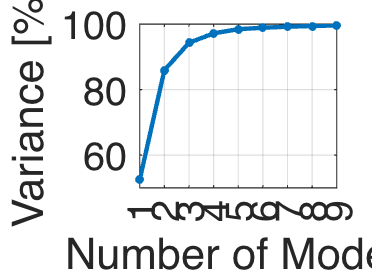

Xsnapshots = cat(2,oData{:,2});
% Perform SVD on displacement field
[V,S,~] = svd(Xsnapshots, 0);
% Plot variance description: we expect three modes to capture almost all
% variance. Note we assume data centered around the origin, which is the
% fixed point of our system
customFigure;
l2vals = diag(S).^2;
plot(1:length(l2vals),cumsum(l2vals)/sum(l2vals)*100,'.-','Linewidth',2,'MarkerSize',12)
xlabel('Number of Modes');
ylabel('Variance [%]');
xlim([1 9])
set(gca,'XTick',[1:1:9])

% Define modes
SSMDim = 6; hSSMDim = SSMDim/2;
V_PCA_space = V(:,1:hSSMDim);

Visualize PCA projections

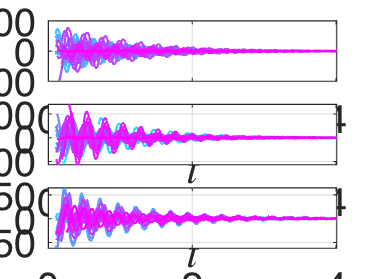

% transform trajectories
pData = oData;
customFigure('subPlot',[numCoord 1]);
labels = ["$u_1$", "$u_2$", "$u_3$"];
for iPlt = 1:hSSMDim
    subplot(numCoord,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    pData{iTraj,2} = transpose(V)*oData{iTraj,2};
    for iObs = 1:hSSMDim
        subplot(numCoord,1,iObs);
        plot(pData{iTraj,1},pData{iTraj,2}(iObs,:),'Linewidth',1)
    end
end

Perform delay-embedding. As observables for the model, we consider all current positions data as well as past measurements (no future ones). We have a minimum of 0 delays, which is augmented by the `overEmbed` variable, so that the number of total delays is `overEmbed`. Delay-embedding in this case is used both for providing velocity-type data and for denoising. We also do some cutting, but it is not necessary in this case.

overEmbed = 25;
[yData, opts_embd] = coordinatesEmbeddingControl(oData, SSMDim, 'OverEmbedding', overEmbed);

The 390 embedding coordinates consist of the 15 measured states and their 25 time-delayed measurements.


embedDim = size(yData{1,2},1);
outdofs = [embedDim-2 embedDim-1 embedDim];
sliceInt = [0.01, Inf];
yDataTrunc = sliceTrajectories(yData, sliceInt);


PCA is still useful in the delay-embeeded space, as the number of modes explaining most of the data should be the dimension of the SSM. Indeed, we get it as more than 90% of variance is explained by the first six PCA modes.

disp('PCA')

PCA


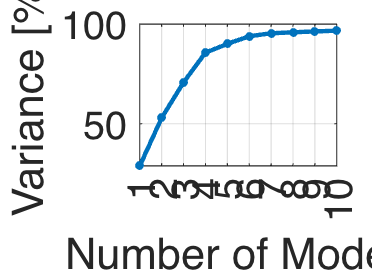

Xsnapshots = cat(2,yDataTrunc{:,2});
% Perform SVD on displacement field
[V,S,~] = svd(Xsnapshots, 0);
% Note we assume data centered around the origin, which is the
% fixed point of our system
customFigure;
maxModesPlot = 10;
l2vals = diag(S).^2;
plot(1:length(l2vals),cumsum(l2vals)/sum(l2vals)*100,'.-','Linewidth',2,'MarkerSize',12)
xlabel('Number of Modes');
ylabel('Variance [%]');
xlim([1 maxModesPlot])
set(gca,'XTick',[1:1:maxModesPlot])


Vde = V(:,1:SSMDim);
% Set reduced-coordinates as PCA projection to the first six modes
etaDataTrunc = yDataTrunc;
for iTraj = 1:size(oData, 1)
    etaDataTrunc{iTraj,2} = transpose(Vde)*yDataTrunc{iTraj,2};
end

% Set test and train trajectories
indTest = [5 15 21 32 38];
indTrain = setdiff(1:size(oData, 1),indTest);

## Geometry

Manifold fitting with prescribed graph. Higher orders tend to overfit.

SSMOrder = 3;
if SSMOrder == 1
    % Need to recompute as the columns of Vde might change in order
    IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder);
    Vde = IMInfo.parametrization.tangentSpaceAtOrigin;
    etaDataTrunc = yDataTrunc;
    for iTraj = 1:size(oData, 1)
        etaDataTrunc{iTraj,2} = transpose(Vde)*yDataTrunc{iTraj,2};
    end
else
    IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder,'reducedCoordinates',etaDataTrunc(indTrain,:));
    IMInfo.chart.map = @(x) transpose(Vde)*x;
end

Evaluate learning of geometry.

disp('Results of geometry fit:')

Results of geometry fit:


yRec = liftTrajectories(IMInfo, etaDataTrunc);
normedTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
meanErrorGeoTrain = mean(normedTrajDist(indTrain))*100

meanErrorGeoTrain = 5.1977

meanErrorGeoTest = mean(normedTrajDist(indTest))*100

meanErrorGeoTest = 4.8375

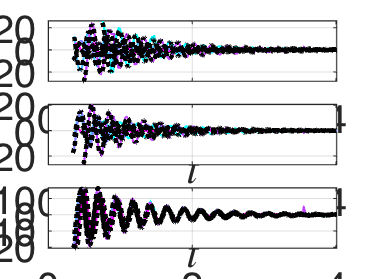


% Plot test data
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end

for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
    end
end

for iTraj = 1:length(indTest)
        yRec = liftTrajectories(IMInfo, etaDataTrunc(indTest(iTraj),:));
        errorGeoTest(iTraj) = computeTrajectoryErrors(yRec, yDataTrunc(indTest(iTraj),:))*100;
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yRec{1,1},yRec{1,2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end

## Reduced dynamics

Cubic order dynamics halves the trajectory error of linear dynamics. The `Map` case seems more accurate than the `Flow` one.

ROMOrder = 3;
RDInfo = IMDynamicsFlow(etaDataTrunc(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'default');

Estimation of the reduced dynamics...  Done. 


RDInfo.eigenvaluesLinPartFlow(1:3)

ans =   -1.0728 +26.3872i
  -1.1633 +26.4678i
  -1.1791 +27.0399i


Evaluate learning of reduced dynamics.

disp('Errors for the dynamics on reduced-coordinates:')

Errors for the dynamics on reduced-coordinates:


etaRec = advectRD(RDInfo, etaDataTrunc);
normedTrajDist = computeTrajectoryErrors(etaRec, etaDataTrunc);
meanErrorDynTrain = mean(normedTrajDist(indTrain))*100

meanErrorDynTrain = 8.1562

meanErrorDynTest = mean(normedTrajDist(indTest))*100

meanErrorDynTest = 9.3638

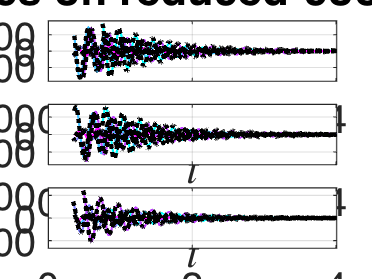


customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1); title('Dynamics on reduced-coordinates')
labels = ["$\eta_1$", "$\eta_2$", "$\eta_3$"];
for iPlt = 1:hSSMDim
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
yLimits = [0 0 0];
for iTraj = 1:length(indTest)
    for iObs = 1:hSSMDim
        subplot(numCoord,1,iObs);
        plot(etaDataTrunc{indTest(iTraj),1},etaDataTrunc{indTest(iTraj),2}(iObs,:),'Linewidth',1)
        yLimits(iObs) = max([max(abs(etaDataTrunc{indTest(iTraj),2}(iObs,:))) yLimits(iObs)]);
        ylim([-1 1]*1.1*yLimits(iObs))
    end
end

for iTraj = 1:length(indTest)
    for iObs = 1:hSSMDim
        subplot(numCoord,1,iObs);
        plot(etaRec{indTest(iTraj),1},etaRec{indTest(iTraj),2}(iObs,:),'k:','Linewidth',2)
    end
end

## Switch to observable coordinates

% Define custom chart only based on tip data and 1 delay
outdofsNew = [28 29 30];
yDataTruncNew = yDataTrunc;
numDesiredObs = 30;

for iTraj = 1:size(yData,1)
    yDataTruncNew{iTraj,2} = yDataTrunc{iTraj,2}(end-(numDesiredObs-1):end,:);
end

IMInfo_paramonly = IMGeometry(yDataTruncNew(indTrain,:), SSMDim, SSMOrder,'reducedCoordinates',etaDataTrunc(indTrain,:),'style','custom');
tanSpace0_not_orth = IMInfo_paramonly.parametrization.tangentSpaceAtOrigin;
tanSpace0 = orthogonalizeGramSchmidt(tanSpace0_not_orth);
% Change coordinates
etaDataTruncNew = etaDataTrunc;
for iTraj = 1:size(etaDataTrunc,1)
    etaDataTruncNew{iTraj,2} = transpose(tanSpace0)*tanSpace0_not_orth*etaDataTrunc{iTraj,2};
end
% Fit new parametrization
IMInfo_paramonly = IMGeometry(yDataTruncNew(indTrain,:), SSMDim, SSMOrder,'reducedCoordinates',etaDataTruncNew(indTrain,:),'Ve',tanSpace0,'style','custom');
disp('Results of new parametrization fit:')

Results of new parametrization fit:


yRec = liftTrajectories(IMInfo_paramonly, etaDataTruncNew);
normedTrajDist = computeTrajectoryErrors(yRec, yDataTruncNew);
meanErrorGeoTrain = mean(normedTrajDist(indTrain))*100

meanErrorGeoTrain = 4.1483

meanErrorGeoTest = mean(normedTrajDist(indTest))*100

meanErrorGeoTest = 3.8719


% Fit the chart for tangent space
IMInfo_chartonly = IMGeometry(etaDataTruncNew(indTrain,:), SSMDim, SSMOrder,'reducedCoordinates',yDataTruncNew(indTrain,:));%,'Ve',transpose(tanSpace0),'style','custom');
disp('Results of new chart fit:')

Results of new chart fit:


etaRec = liftTrajectories(IMInfo_chartonly, yDataTruncNew);
normedTrajDist = computeTrajectoryErrors(etaRec, etaDataTruncNew);
meanErrorGeoTrain = mean(normedTrajDist(indTrain))*100

meanErrorGeoTrain = 7.3663

meanErrorGeoTest = mean(normedTrajDist(indTest))*100

meanErrorGeoTest = 6.8217


% Store the chart and the parameterization
IMInfo = struct('chart', IMInfo_chartonly.parametrization, 'parametrization', IMInfo_paramonly.parametrization);

ROMOrder = 3;
RDInfo = IMDynamicsFlow(etaDataTruncNew(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'default');

Estimation of the reduced dynamics...  Done. 


RDInfo.eigenvaluesLinPartFlow(1:3)

ans =   -1.0728 +26.3872i
  -1.1633 +26.4678i
  -1.1791 +27.0399i


Rauton = RDInfo.reducedDynamics.map;
disp('Errors for the dynamics on reduced-coordinates:')

Errors for the dynamics on reduced-coordinates:


etaRec = advectRD(RDInfo, etaRec);
normedTrajDist = computeTrajectoryErrors(etaRec, etaDataTruncNew);
meanErrorDynTrain = mean(normedTrajDist(indTrain))*100

meanErrorDynTrain = 15.0802

meanErrorDynTest = mean(normedTrajDist(indTest))*100

meanErrorDynTest = 11.3020

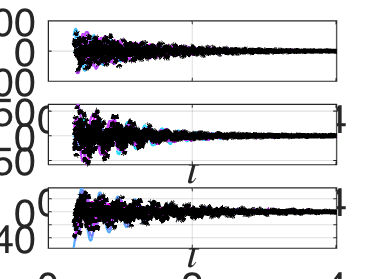

yRec = liftTrajectories(IMInfo, etaRec);

% Plot trajectory data
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1); indPlot = indTrain(isinf(normedTrajDist(indTrain)) == 0);

for iPlt = 1:length(outdofsNew)
    subplot(numCoord,1,iPlt); colororder(cool(length(indPlot)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iTraj = 1:length(indPlot)
    for iObs = 1:length(outdofsNew)
        subplot(numCoord,1,iObs);
        plot(yDataTruncNew{indPlot(iTraj),1},yDataTruncNew{indPlot(iTraj),2}(outdofsNew(iObs),:),'Linewidth',1)
    end
end
for iTraj = 1:length(indPlot)
    for iObs = 1:length(outdofsNew)
        subplot(numCoord,1,iObs);
        plot(yRec{indPlot(iTraj),1},yRec{indPlot(iTraj),2}(outdofsNew(iObs),:),'k:','Linewidth',2)
    end
end

## Load controlled data

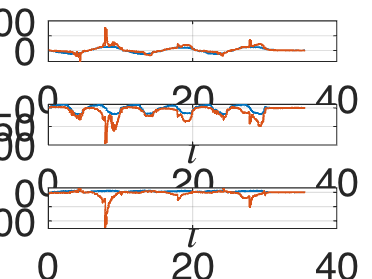

% Load and process tpwl data for tip coords only
% load figure8_amp15
%load koopman_data_figureEight
load tpwl_data

y = y(1:end, :); % all the markers

zu = {};
%keptIdxs = 100:600;
keptIdxs = 1:size(y,2);
zu{1,1} = t(keptIdxs); zu{1,2} = y(:, keptIdxs) - y(:, end); uCell{1,1} = t(keptIdxs); uCell{1,2} = u(:, keptIdxs); Yu = zu; Udelay = uCell;
for iTraj = 1:size(Yu, 1)
    Yu{iTraj,1} = zu{iTraj,1}(2:end); 
    Yu{iTraj,2} = [zu{iTraj,2}(:,1:end-1); zu{iTraj,2}(:,2:end)]; 
    Udelay{iTraj,1} = uCell{iTraj,1}(2:end); 
    Udelay{iTraj,2} = uCell{iTraj,2}(:,2:end); 
end  

% v then w mapping
xData = projectTrajectories(IMInfo, Yu); % Project down
yDataRemapped = liftTrajectories(IMInfo, xData); % Project up

% Plot data
outdofsNew = [28 29 30];
outdofsActual = [28 29 30];
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofsNew)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iTraj = 1:length(size(yDataRemapped, 1))
    for iObs = 1:length(outdofsNew)
        subplot(numCoord,1,iObs);
        plot(Yu{iTraj,1},Yu{iTraj,2}(outdofsActual(iObs),:),'Linewidth',1)
    end
end
for iTraj = 1:length(size(yDataRemapped, 1))
    for iObs = 1:length(outdofsNew)
        subplot(numCoord,1,iObs);
        plot(yDataRemapped{iTraj,1},yDataRemapped{iTraj,2}(outdofsNew(iObs),:),'Linewidth',1)
    end
end

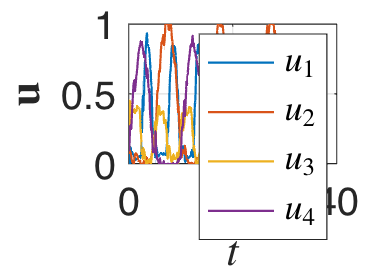


% Plot control inputs
customFigure;
plot(uCell{1,1}, uCell{1,2},'Linewidth',1);
xlabel('$t$','Interpreter','latex');
ylabel('$\mathbf{u}$','Interpreter','latex');
legend('$u_1$','$u_2$','$u_3$','$u_4$','location','NE','Interpreter','latex');